% Load the data
opts = detectImportOptions("C:\Users\SWARNASMITA\OneDrive\Documents\heart.csv");
data = readtable("C:\Users\SWARNASMITA\OneDrive\Documents\heart.csv", opts);

% Convert table to array for numerical operations
dataArray = table2array(data);

% Standardize the data (zero mean and unit variance)
standardizedData = zscore(dataArray);

% Update the data table with standardized values
data{:, vartype('numeric')} = standardizedData;

% Display the full standardized data table with column names
disp(data);

       age         sex         cp       trestbps      chol         fbs       restecg     thalach       exang       oldpeak      slope         ca         thal      target 
    _________    _______    ________    ________    _________    ________    _______    __________    ________    _________    ________    ________    ________    _______

     -0.26831    0.66118    -0.91531    -0.37745     -0.65901    -0.41867    0.89082       0.82092    -0.71194    -0.060859     0.99495      1.2086      1.0893    -1.0262
     -0.15


% Compute covariance matrix
covMatrix = cov(standardizedData)

covMatrix =     1.0000   -0.1032   -0.0720    0.2711    0.2198    0.1212   -0.1327   -0.3902    0.0882    0.2081   -0.1691    0.2716    0.0723   -0.2293
   -0.1032    1.0000   -0.0411   -0.0790   -0.1983    0.0272   -0.0551   -0.0494    0.1392    0.0847   -0.0267    0.1117    0.1984   -0.2795
   -0.0720   -0.0411    1.0000    0.0382   -0.0816    0.0793    0.0436    0.3068   -0.4015   -0.1747    0.1316   -0.1762   -0.1633    0.4349
    0.2711   -0.0790    0.0382    1.0000    0.1280    0.1818   -0.1238   -0.0393    0.0612    0.1874   -0.1204    0.1046    0.0593   -0.1388
    0.2198   -0.1983   -0.0816    0.1280    1.0000    0.0269   -0.1474   -0.0218    0.0674    0.0649   -0.0142    0.0743    0.1002   -0.1000
    0.1212    0.0272    0.0793    0.1818    0.0269    1.0000   -0.1041   -0.0089    0.0493    0.0109   -0.0619    0.1372   -0.0422   -0.0412
   -0.1327   -0.0551    0.0436   -0.1238   -0.1474   -0.1041    1.0000    0.0484   -0.0656   -0.0501    0.0861   -0.0781   -0.0205    0.1345
 


% Calculate eigenvalues and eigenvectors
[eigenVectors, eigenValuesMatrix] = eig(covMatrix);
eigenValues = diag(eigenValuesMatrix);

% Sort eigenvalues in descending order (important for PCA)
[eigenValuesSorted, indices] = sort(eigenValues, 'descend')

eigenValuesSorted =     3.3137
    1.5882
    1.2304
    1.1793
    0.9992
    0.9727
    0.8764
    0.7680
    0.7338
    0.6334


indices =     14
    13
    12
    11
    10
     9
     8
     7
     6
     5


sortedEigenVectors = eigenVectors(:, indices)  % Sorted eigenvectors

sortedEigenVectors =    -0.2520    0.4347    0.0372    0.0785    0.2911    0.2001    0.2496   -0.2289   -0.3938    0.0098   -0.1032   -0.5361    0.0664   -0.2069
   -0.1126   -0.3975   -0.4984   -0.2794   -0.0535   -0.0274    0.1844   -0.0998   -0.2139    0.5347   -0.2149   -0.0760   -0.2674   -0.0118
    0.2819    0.2446   -0.0681   -0.4292   -0.1852    0.2358    0.2162    0.1243   -0.2908    0.1668    0.5294    0.1978    0.2946   -0.0346
   -0.1431    0.4454   -0.1225   -0.1706   -0.2402    0.1441   -0.3103   -0.6273    0.2846    0.1283   -0.0473    0.2230   -0.1389    0.0102
   -0.1022    0.3684    0.0035    0.5369   -0.3067    0.0048   -0.0618    0.4127   -0.1279    0.4897   -0.0824    0.1509   -0.1041    0.0284
   -0.0604    0.3123   -0.3407   -0.3490    0.2308   -0.2853   -0.5181    0.3650   -0.2227   -0.1703   -0.1743   -0.0203    0.0285    0.1204
    0.1127   -0.2376    0.2858   -0.0557    0.2791    0.6364   -0.5112    0.0766   -0.0886    0.2664   -0.1033    0.0066    0.0170   


% Calculate the percentage of variance explained by each component
varianceExplained = (eigenValuesSorted / sum(eigenValuesSorted)) * 100;

% Display the variance explained by each component
disp('Variance explained by each component:');

Variance explained by each component:


disp(varianceExplained);

   23.6696
   11.3443
    8.7889
    8.4238
    7.1372
    6.9481
    6.2602
    5.4859
    5.2417
    4.5244
    3.7724
    3.1059
    2.6616
    2.6360



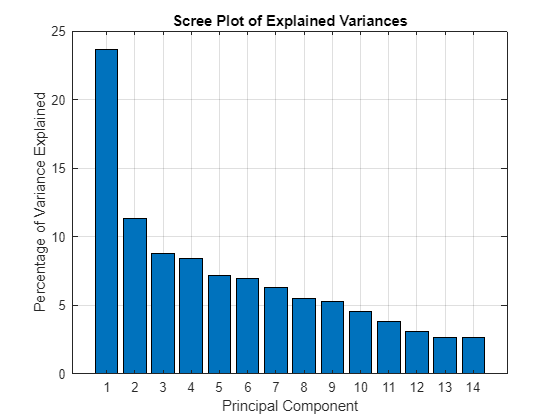


% Plotting a scree plot of the explained variances for each component
figure;
bar(varianceExplained);
xlabel('Principal Component');
ylabel('Percentage of Variance Explained');
title('Scree Plot of Explained Variances');
grid on;


% Select the top k eigenvectors (e.g., top 8 components)
k = 8;  % Number of principal components to keep
principalComponents = sortedEigenVectors(:, 1:k);

% Project the standardized data onto the new subspace
projectedData = standardizedData * principalComponents

projectedData =    -0.1187   -1.4312   -1.4602    0.6744    0.5616    1.4935   -0.0713    0.0363
   -2.7862   -0.3164   -0.4325   -2.0975   -1.3552   -1.5317   -1.4689    0.6017
   -3.1798   -0.9329    1.3655   -1.3351   -0.2799    0.7371   -0.3783   -1.3795
   -0.0860   -0.5881   -1.3365    0.6185    0.4924    1.4356   -0.3856   -1.5715
   -2.2943    2.0744    0.3002   -0.0445    2.3937    0.5730   -1.0219    1.6689
    0.3293    0.1573    1.9968    0.8470    0.5847   -1.2165    1.3535    0.7490
   -2.3278   -0.3946    2.0417   -0.8392    1.4701    1.9176    0.3225    2.7544
   -2.1538    0.0824   -0.8747    0.8384   -1.2742   -0.4917   -0.4235   -1.1186
   -0.0242   -1.3520   -1.0281    1.0780   -0.7557   -0.5422    0.6016   -0.1871
   -2.9350   -0.5821    0.3501    0.3054    0.2169   -0.9489    0.8762    0.7439



% Define colors based on a specific column or use random colors
labels = dataArray(:, end);  % Assuming the last column is the label

% Create a table for loadings along with feature names
loadings = sortedEigenVectors(:, 1:k);  % Loadings for the top k components
columnNames = data.Properties.VariableNames;  % Get the feature names

% Create a table for loadings along with feature names
loadings = sortedEigenVectors(:, 1:k);  % Loadings for the top k components
columnNames = data.Properties.VariableNames;  % Get the feature names

% Initialize an empty table to hold the loadings and feature names
loadingTable = table();

% Loop through the features and add their loadings for each principal component
for i = 1:k
    loadingTable = [loadingTable, table(loadings(:, i), 'VariableNames', {['PC' num2str(i)]})];
end

% Add feature names as the first column in the table
loadingTable.Feature = columnNames';

% Display the loadings table
disp('Loadings for the top 8 principal components:');

Loadings for the top 8 principal components:


disp(loadingTable);

       PC1          PC2          PC3          PC4          PC5           PC6           PC7           PC8         Feature   
    _________    _________    _________    _________    __________    _________    ___________    _________    ____________

     -0.25205       0.4347     0.037196     0.078528       0.29112      0.20012         0.2496     -0.22893    {'age'     }
     -0.11262     -0.39753     -0.49836     -0.27938     -0.053534    -0.027449         0.1844    -0.099757    {'sex'     }
      0.28192      0.24459    -0.068129     -0.42916      -0.18522      0.23581        0.21616       0.1243    {'cp'      }
     -0.14308      0.44536     -0.12251     -0.17058      -0.24017      0

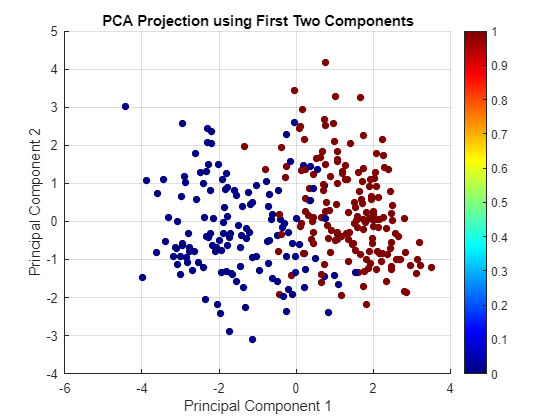


% Plot the first two components (you can modify this to use more components)
figure;
scatter(projectedData(:, 1), projectedData(:, 2), 30, labels, 'filled');
colormap(jet);  % Color scheme for variety
colorbar;  % Show color scale if you're using labels
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA Projection using First Two Components');
grid on;

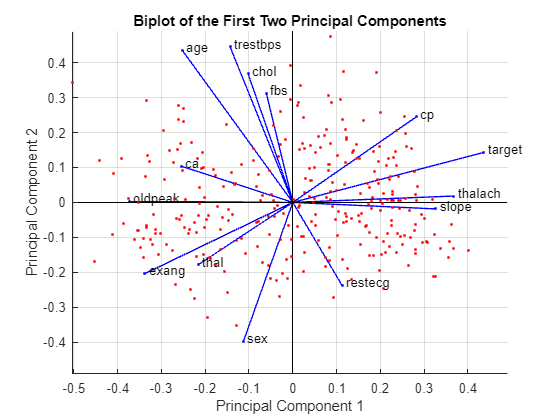


% Display the names of the columns in your dataset
columnNames = data.Properties.VariableNames;

% **Fix: Project only the first 2 components for the biplot**
% Use the first two principal components for biplot
biplot(loadings(:, 1:2), 'Scores', projectedData(:, 1:2), 'VarLabels', columnNames);
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('Biplot of the First Two Principal Components');
grid on;


% Show the features that have the highest loadings for the first 2 principal components
for i = 1:8  % Show top features for the first 2 components
    [~, sortedIdx] = sort(abs(loadings(:, i)), 'descend');  % Sort by absolute value of loadings
    fprintf('\nTop features for Principal Component %d:\n', i);
    for j = 1:2  % Display top 4 features for each component
        fprintf('%s (Loading: %.4f)\n', columnNames{sortedIdx(j)}, loadings(sortedIdx(j), i));
    end
end


Top features for Principal Component 1:


target (Loading: 0.4364)
oldpeak (Loading: -0.3734)



Top features for Principal Component 2:


trestbps (Loading: 0.4454)
age (Loading: 0.4347)



Top features for Principal Component 3:


sex (Loading: -0.4984)
slope (Loading: -0.3711)



Top features for Principal Component 4:


chol (Loading: 0.5369)
cp (Loading: -0.4292)



Top features for Principal Component 5:


ca (Loading: 0.4309)
thal (Loading: -0.4196)



Top features for Principal Component 6:


restecg (Loading: 0.6364)
thal (Loading: 0.4165)



Top features for Principal Component 7:


fbs (Loading: -0.5181)
restecg (Loading: -0.5112)



Top features for Principal Component 8:


trestbps (Loading: -0.6273)
chol (Loading: 0.4127)


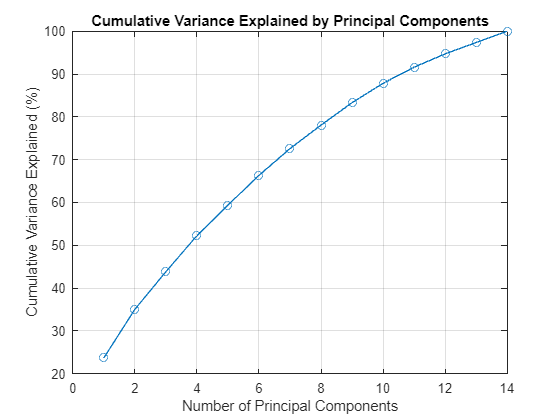



% Cumulative variance plot
cumulativeVariance = cumsum(varianceExplained);
figure;
plot(cumulativeVariance, '-o');
xlabel('Number of Principal Components');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Variance Explained by Principal Components');
grid on;


% Find the number of components to reach a chosen variance threshold
threshold = 75;  % Desired cumulative variance threshold (e.g., 75%)
num_components = find(cumulativeVariance >= threshold, 1);
fprintf('Number of components to reach %.1f%% variance: %d\n', threshold, num_components);              

Number of components to reach 75.0% variance: 8
